l = 5;
p = 4;
n = 10;
m = 12;
num_trials = 50;
num_its = 2000; % number of iterations
num_corrupt = 20; % number of corruption
q = 1-num_corrupt/(m*p*n); % quantile
k = 6 %number of corrupted rows

%corruptions are generated from normal distribution
mean_corrupt = 100;
deviation_corrupt = 20;

k = 6

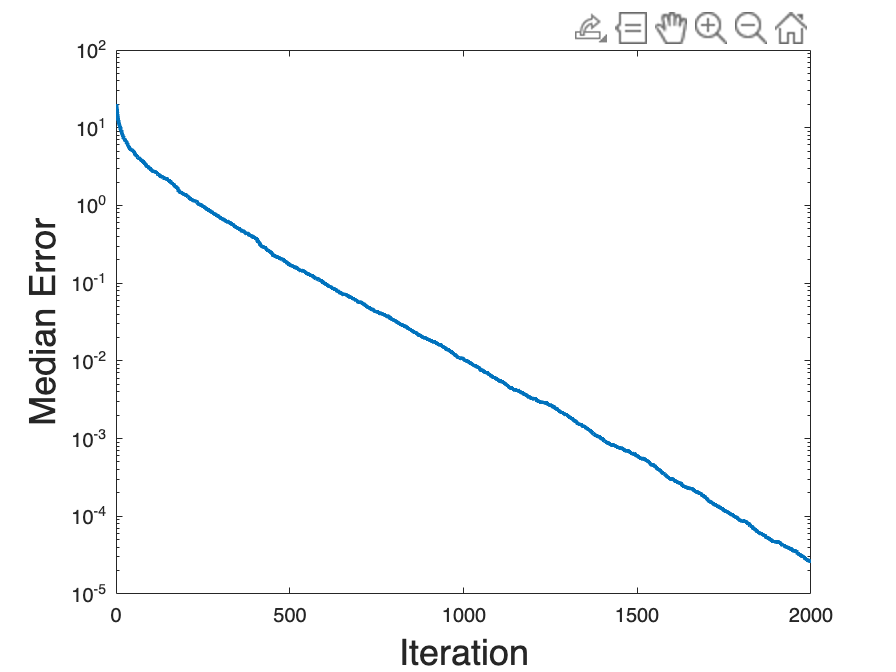

errs_matrix = zeros(num_trials, num_its+1);
% Perform trials
for t = 1:num_trials
    
    %generate tensors
    A = randn(m,l,n);
    X_true = randn(l,p,n);
    B = tprod(A,X_true);

    % Generate random corruption values for each trial
    corruption_values = mean_corrupt + deviation_corrupt*randn(num_corrupt, 1);

    % Generate k random row indices to corrupt
    corrupt_rows = randsample(m, k);
    
    % Distribute num_corrupt corruptions uniformly across the k rows
    for i = 1:num_corrupt
        % Select a random row from the chosen rows
        row_idx = corrupt_rows(randsample(k, 1));
        
        % Randomly select indices for the other dimensions
        col_idx = randsample(p, 1);
        depth_idx = randsample(n, 1);
    
        % Apply the corruption value
        B(row_idx, col_idx, depth_idx) = B(row_idx, col_idx, depth_idx) + corruption_values(i);
    end


    % Run QTRK
    [~, its] = QTRK_new(A,B, randn(l,p,n), num_its, q); % Adjust q as needed
  
    % Record errors for the current trial
    errs = zeros(num_its + 1, 1);
    for j = 1:num_its + 1
        est = its{j} - X_true; % Adjust X_true according to your setup
        errs_matrix(t,j) = norm(est(:));
    end
end

% Calculate median errors across trials
median_errs = median(errs_matrix);

% Plot median errors vs iterations
semilogy(median_errs, 'LineWidth', 2);
%title('Median Errors across Trials');
xlabel('Iteration', FontSize=18);
ylabel('Median Error', FontSize=18);
xlim([0, num_its]);